Filter with 3-pt averager 

% Define the filter coefficient vector for the 3-point averager
bb = 1/3 * ones(1,3);

% Generate the length-10 pulse signal and pad it with zeros
xx = [ones(1,10), zeros(1,5)];

% Process the input signal using firfilt
yy = firfilt(bb, xx);

 Plot Input and Output Signals

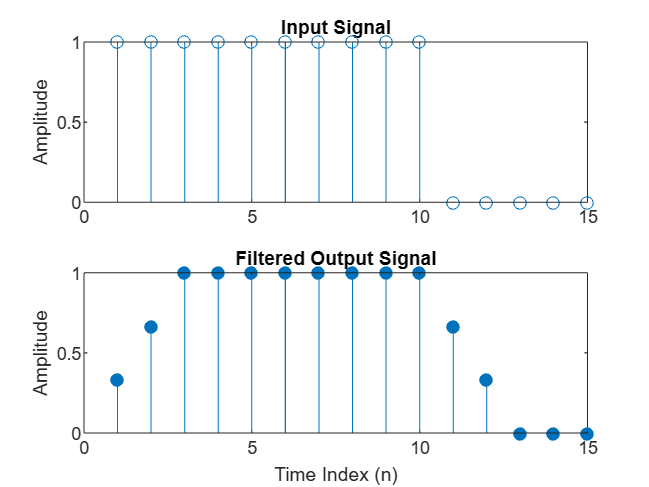

% Define the time indices
nn = 1:length(xx);

% Create a two-panel display using subplot
subplot(2,1,1);
stem(nn, xx(nn))
title('Input Signal')
ylabel('Amplitude')

subplot(2,1,2);
stem(nn, yy(nn), 'filled') % Make black dots
title('Filtered Output Signal')
xlabel('Time Index (n)')
ylabel('Amplitude')

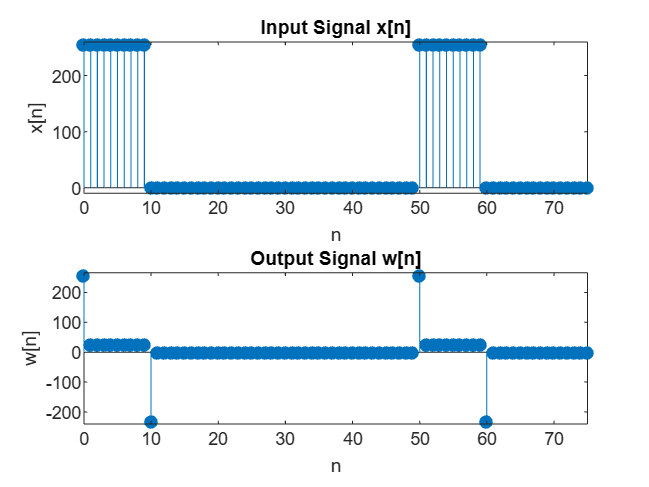

xx = 256 * (rem(0:100, 50) < 10);
bb = [1, -0.9];
ww = firfilt(bb, xx);

n = 0:100;
n1 = 0:length(ww)-1; % the answer to 3.1b (102)

subplot(2, 1, 1);
stem(n, xx, 'filled');
title('Input Signal x[n]');
xlabel('n');
ylabel('x[n]');
axis([0 75 -10 260]);

subplot(2, 1, 2);
stem(n1, ww, 'filled');
title('Output Signal w[n]');
xlabel('n');
ylabel('w[n]');
axis([0 75 min(ww)-10 max(ww)+10]);

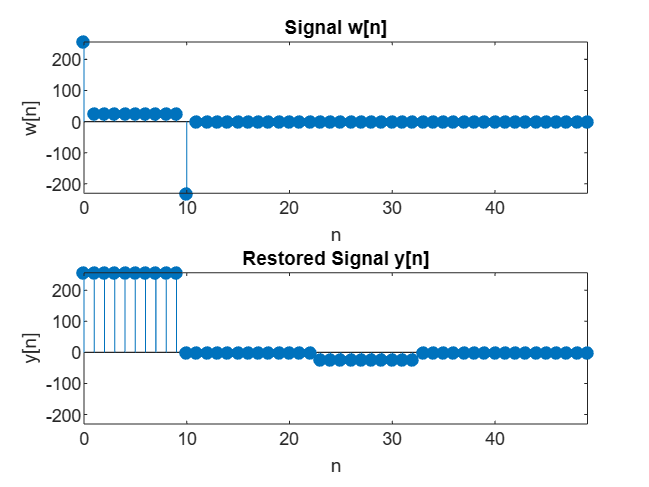

bb = ones(1,23);
for M = 0:22
    bb(M+1)=(0.9^M);
end
yy = firfilt(bb, ww);

n1 = 0:length(ww)-1;
n2 = 0:length(yy)-1;

figure;
subplot(2, 1, 1);
stem(n1, ww, 'filled');
title('Signal w[n]');
xlabel('n');
ylabel('w[n]');
axis([0 49 min(ww) max(ww)]);

subplot(2, 1, 2);
stem(n2, yy, 'filled');
title('Restored Signal y[n]');
xlabel('n');
ylabel('y[n]');
axis([0 49 min(ww) max(ww)]);

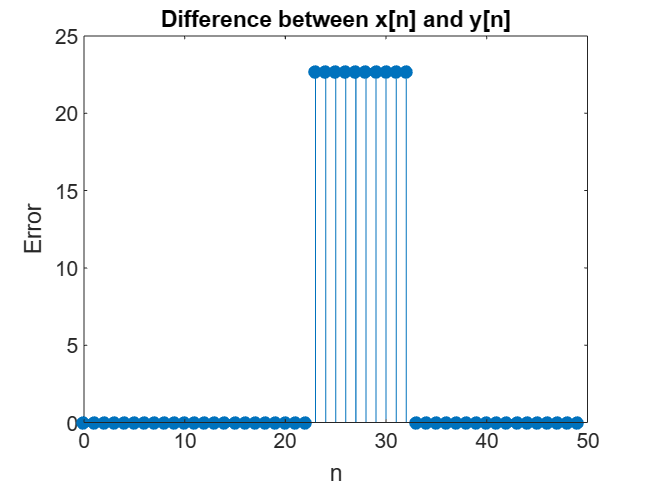


yy1 = yy(1:length(xx));
error = xx - yy1;

figure;
stem(0:49, error(1:50), 'filled');
title('Difference between x[n] and y[n]');
xlabel('n');
ylabel('Error');

difference = abs(xx(1:50) - yy(1:50));
worsecase = max(difference);
disp(num2str(worsecase)); % 22.6891

22.6891


load labdat.mat;

fs = 8000;
delay = 0.2;
r = 0.9;
P = round(fs * delay);

for n=1601:length(x2)
    y1(n) = x2(n) + r*x2(n-P);
end

soundsc(y1);


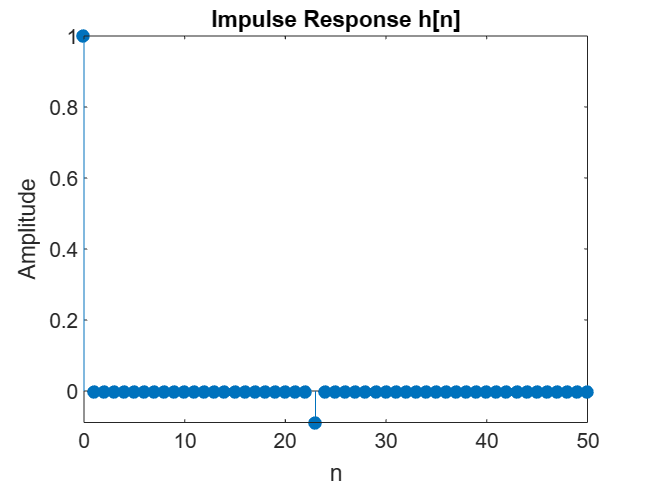

q = 0.9;
h1 = [1, -q];

bb = zeros(1,23);
for M = 0:22
    bb(M+1) = (0.9^M);
end

impulse = [1, zeros(1, 100)];

w = firfilt(h1, impulse);
yy = firfilt(bb, w);

figure;
stem(0:length(yy)-1, yy, 'filled');
title('Impulse Response h[n]');
xlabel('n');
ylabel('Amplitude');
axis([0 50 min(yy) max(yy)]);

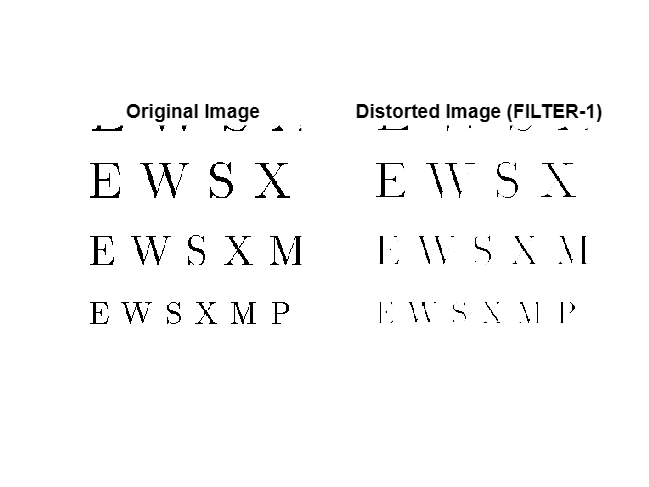

% (a) Load in the image echart.mat with the load command.
load echart.mat;

% (b) Pick q D 0:9 in FILTER-1 and filter the image echart in both directions.
q = 0.9;
bdiffh = [1, q];

% Apply FILTER-1 horizontally
ech90_horizontal = conv2(echart, bdiffh, 'same');

% Apply FILTER-1 vertically to the result of the horizontal filtering
ech90 = conv2(ech90_horizontal, bdiffh', 'same');

% Display the distorted image
figure;
subplot(1, 2, 1);
imshow(uint8(echart));
title('Original Image');

subplot(1, 2, 2);
imshow(uint8(ech90));
title('Distorted Image (FILTER-1)');

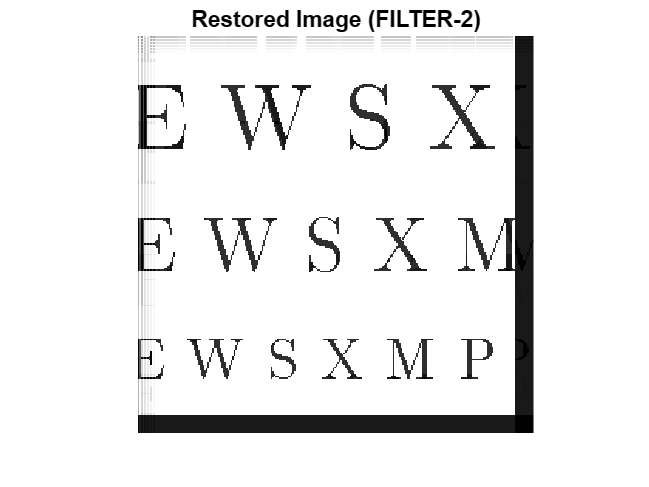


% (c) Deconvolve ech90 with FIR FILTER-2, choosing M D 22 and r D -0:9.
r = -0.9;
M = 22;
brestore = r.^(0:M);

% Deconvolve with FILTER-2
ech_restored = conv2(ech90, brestore, 'same');
ech_brestored = conv2(ech_restored, brestore', 'same');

% Display the deconvolved image
figure;
imshow(uint8(ech_brestored));
title('Restored Image (FILTER-2)');


% Evaluate worst-case error
min_height = min(size(echart, 1), size(ech_brestored, 1));
min_width = min(size(echart, 2), size(ech_brestored, 2));

worst_case_error = max(abs(echart(1:min_height, 1:min_width) - ech_brestored(1:min_height, 1:min_width)), [], 'all');
fprintf('Worst-case error: %f\n', worst_case_error);

Worst-case error: 348.162813


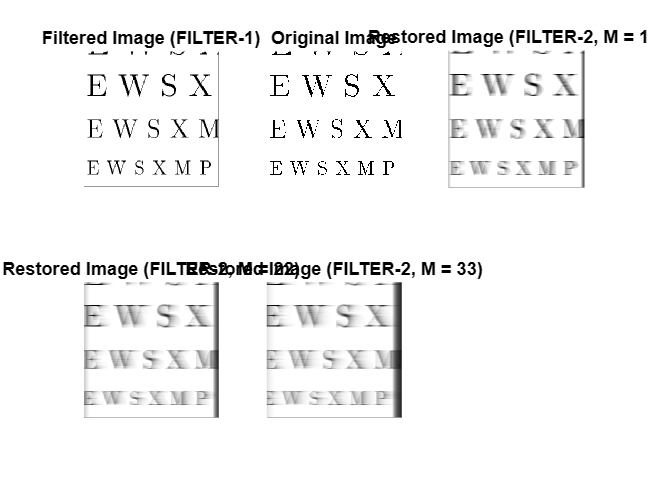

% Load the image echart.mat
load echart.mat;

% Set q for FILTER-1
q = 0.9;

% Apply FILTER-1 along the horizontal direction
ech90_horizontal = conv2(echart, [1, q], 'same');

% Apply FILTER-1 along the vertical direction
ech90 = conv2(ech90_horizontal, [1; q], 'same');

% Deconvolve ech90 with different FIR filters for FILTER-2
r = 0.9;
M_values = [11, 22, 33];
num_M_values = length(M_values);
restored_images = cell(1, num_M_values);

for k = 1:num_M_values
    M = M_values(k);
    bb_filter2 = r.^(0:M);

    % Apply FILTER-2 for deconvolution
    restored_images{k} = conv2(ech90, bb_filter2, 'same');
end

% Display the results
figure;

% Display Filtered Image (FILTER-1)
subplot(2, 3, 1);
imshow(ech90, []);
title('Filtered Image (FILTER-1)');

% Display Original Image
subplot(2, 3, 2);
imshow(echart, []);
title('Original Image');

% Display Restored Images for different M values (FILTER-2)
for k = 1:num_M_values
    M = M_values(k);
    subplot(2, 3, k + 2);
    imshow(restored_images{k}, []);
    title(['Restored Image (FILTER-2, M = ', num2str(M), ')']);
end


% Print the best M value
errors = cellfun(@(x) sum(abs(x(:) - echart(:))), restored_images);
[~, best_index] = min(errors);
best_M = M_values(best_index);
disp(['Best M value for FILTER-2: ', num2str(best_M)]);

Best M value for FILTER-2: 11



% Calculate and print worst-case error in terms of gray levels for each filter
for k = 1:num_M_values
    M = M_values(k);
    bb_filter2 = r.^(0:M);

    % Deconvolve with FILTER-2
    ech_restored = conv2(ech90, bb_filter2, 'same');
    ech_brestored = conv2(ech_restored, bb_filter2', 'same');

    % Evaluate worst-case error
    min_height = min(size(echart, 1), size(ech_brestored, 1));
    min_width = min(size(echart, 2), size(ech_brestored, 2));

    worst_case_error = max(abs(echart(1:min_height, 1:min_width) - ech_brestored(1:min_height, 1:min_width)), [], 'all');
    disp(worst_case_error);
    
    % Convert worst-case error to gray levels
    gray_levels_error = worst_case_error / 256;

    fprintf('For M = %d, worst-case error in terms of gray levels: %.4f\n', M, gray_levels_error);
end

   4.7145e+04



For M = 11, worst-case error in terms of gray levels: 184.1594


   7.6206e+04



For M = 22, worst-case error in terms of gray levels: 297.6779


   8.6751e+04



For M = 33, worst-case error in terms of gray levels: 338.8695
